**SimpleSonarRange.mlx is a utility to read sonar range**

Reading a Maxbox Sonar Range sensor via matlab.

Define the inputs the system takes in here as well as any outputs generated.

Inputs are voltage from sensor.

Outputs are a graph of accuracy data.

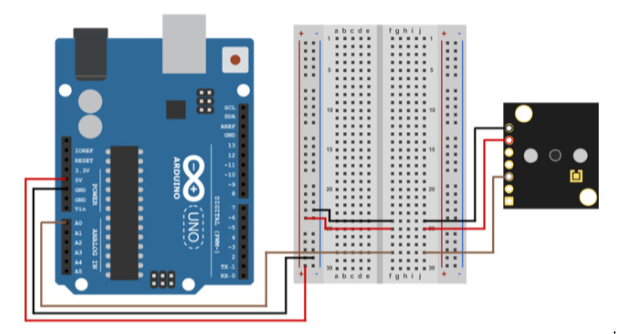

Connect wires as shown above.

Jack Levitsky and CJ Hilty, 3/25/2022, Revision #A

clc             %clear command window
clear           %clear MATLAB workspace

**Set up robot control system **(code that runs once)

 [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO('COM8'); % COM8 for Jack, COM10 for CJ

Updating server code on board Uno (COM8). This may take a few minutes.


Error using SimpleSonarRange>SETUPARDUINO (line 54)
Cannot program board Uno (COM8). Please make sure the board is supported and the port and board type are correct. For more information, see Arduino Hardware Troubleshooting.



beep;

%Configure test loop to collect n data points
nTests = input(['Enter number of range test positions, then hit enter']);
clc

%Create a variable to hold experimental position data
positionData=zeros(nTests,2);

r=rateControl(1);
beep;
beep;

**Run robot control loop **(code that runs over and over)

 controlFlag = 1;           %create a loop control
 while (controlFlag <= nTests)  
     rangeData=SENSE(robotArduino, rawRangeIn);
        THINK();    %No thoughts, head empty
        ACT();      %Command robot actuators

        positionData(controlFlag,1)=input("enter actual distance (cm)" );
        gtest=input("move sonar to new range, type G, then hit enter ","s");
        positionData(controlFlag,2)=rangeData;
        waitfor(r)          %wait for loop to complete
        controlFlag=controlFlag+1;
 end

sense


I am not the brightest


I'm not the best actor


ans = 19

controlFlag = 2

sense


I am not the brightest


I'm not the best actor


ans = 18

controlFlag = 3

sense


I am not the brightest


I'm not the best actor


ans = 14

controlFlag = 4

sense


I am not the brightest


I'm not the best actor


ans = 24

controlFlag = 5

sense


I am not the brightest


I'm not the best actor


ans = 11

controlFlag = 6

sense


I am not the brightest


I'm not the best actor


ans = 8

controlFlag = 7

sense


I am not the brightest


I'm not the best actor


ans = 10

controlFlag = 8

sense


I am not the brightest


I'm not the best actor


ans = 10

controlFlag = 9

sense


I am not the brightest


I'm not the best actor


ans = 22

controlFlag = 10

sense


I am not the brightest


I'm not the best actor


ans = 12

controlFlag = 11

sense


I am not the brightest


I'm not the best actor


Error using SimpleSonarRange>blink (line 67)
Not enough memory on the target to buffer the data. Data dropped may be seen in the logged data.

**Mission data processing**

This code will allow up to plot measured versus actual range positions.

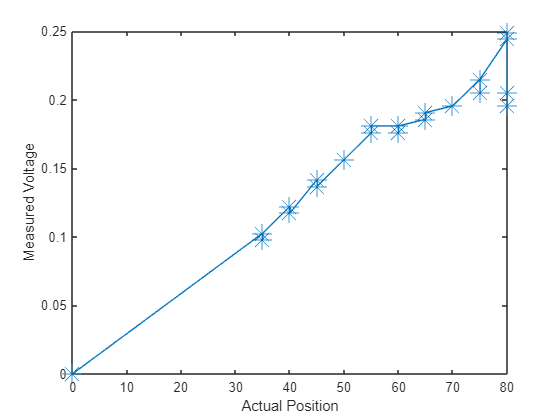

plot(positionData(:,1), positionData(:,2),'-*', MarkerSize=15);
xlabel("Actual Position")
ylabel("Measured Voltage")

### Manually Run Sense/store

rangeData=SENSE(robotArduino, rawRangeIn);

sense


positionData(end+1,1) = 50; %cm, MANUALLY MODIFY WHEN TESTING
positionData(end,2) = rangeData

positionData =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


**Find unknown distance**

voltage = SENSE(robotArduino,rawRangeIn);

sense


distance=readCenterSonar(voltage)

distance = 47.3924

**Clean shut down**

clc
clear robotArduino
beep
beep

while true
    voltage = SENSE(robotArduino,rawRangeIn);
    distance=readCenterSonar(voltage)
end

**Robot Functions** (store the code's local functions here)

To make things readable, modular, and reusable, your main robot code is as brief as possible while the majority of work is completed by functions

function [robotArduino, rawRangeIn, blinkLED] = SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot
% controller. Inputs: COM port for the arduino. Returns: Ardunio system
% object called robotArdunio, pan servo system object, tilt servo system object and LED system object.
% Pair Programmed by Jack and CJ 2022.


% Create a global arduino object so that it can be used in functions
% a = arduino('setTOYourComNumber','Uno','Libraries,'Servo');
    robotArduino = arduino(COMPORT,'Uno','Libraries','Servo');

% configure pin 13 as digital-out LED
    blinkLED = 'D13';
    configurePin(robotArduino,blinkLED,'DigitalOutput');

% configure pin A2 as an analog input
    rawRangeIn = 'A2';
    configurePin(robotArduino,rawRangeIn,'AnalogInput');

end
    function [] = blink(a,LED,n)
    % Blink toggles Arduino a LED on and off to indicate program running
    % input n = number of blinks
    % no output is returned
    % Jack and CJ 2022
    for bIndex = 1:3*n
        writeDigitalPin(a,LED,0);
        pause(0.1)
        writeDigitalPin(a,LED,1);
        pause(0.1)
    end
end



function [r] = rateSetup();
% Allows the user to set the rate that the control loop will wait for with a
% single call. Useful for changing the rate when you need to somewhere other
% than the setup code.
timeGap = input("Enter how long (in seconds) should pass between demo points and then press ENTER:   ");
setRate = 1/(max(timeGap,0.000001)); % prevent request for infinite rate
r = rateControl(setRate);  % create a rate controller that will make sure the loop of position last MORE than (1/input) seconds, using the waitfor(r) call.
reset(r);                  % reset loop time to zero
end




**Sense Functions **(store all sense related functions here)

function rangeData = SENSE(robotArduino, rawRangeIn)
disp('sense');
rangeData=readVoltage(robotArduino,rawRangeIn);
end
function distance=readCenterSonar(voltage)
% Function that uses calibration data obtained on 3/29/2022 to estimate
% distance from the center sonar in the array.

%Curve fit app results
distance = max((340.7 *voltage - 0.8984),0); % returns minimum of 0. 

end

**Think Functions **(store all think related functions here)

function THINK(time)
%disp('I am not the brightest');
end

**Act Functions **(store all act related functions here)

function ACT(time)
%disp("I'm not the best actor");
end